# Q3. Object Detection *(15 points)*

## 0. Importing a Trained Detector

Load a trained dectector. The detector detects pet faces.

clear;
load("detector.mat")
whos

  Name          Size            Bytes  Class                       Attributes

  detector      1x1                 8  fasterRCNNObjectDetector              



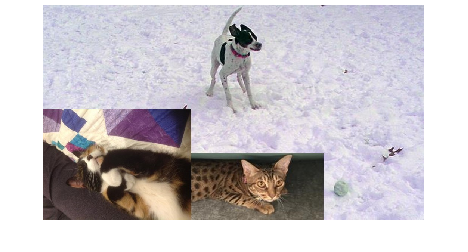

testImage = imread("Q3_testImage.JPG");
imshow(testImage)

## 1. Object Detection (3+7+5 = 15)

###     1.1. Detect Objects (3)

      Use `detector` to detect a pet face in `testImage` variable. Output the following three results.

- bounding box

- score

- label

[bboxes, scores, labels] = detect(detector, testImage)

bboxes =    573   451   119   113
    85   395    64    85
   554    58    60    60


scores = 3×1 single 열 벡터
    0.9054
    0.8981
    0.6416


labels = 3×1 categorical 배열
     Kima 
     Lucy 
     Ginny 


###     1.2. Insert bounding boxes, labels and scores (7)

      Insert the bounding box, label, and score in the image as the figure in the right pane.

newlabels = cell(size(labels))

newlabels = 3×1 cell 배열
    {0×0 double}
    {0×0 double}
    {0×0 double}


for i = 1:height(labels)
    newlabels{i} = [char(labels(i)), ' : ', num2str(scores(i))]
end

newlabels = 3×1 cell 배열
    {'Kima : 0.90542'}
    {0×0 double      }
    {0×0 double      }


newlabels = 3×1 cell 배열
    {'Kima : 0.90542'}
    {'Lucy : 0.8981' }
    {0×0 double      }


newlabels = 3×1 cell 배열
    {'Kima : 0.90542'}
    {'Lucy : 0.8981' }
    {'Ginny : 0.6416'}


detectedImage = insertObjectAnnotation(testImage, "rectangle",...
    bboxes, newlabels)

detectedImage = 575×1020×3 uint8 배열
detectedImage(:,:,1) =

   190   191   193   194   194   193   191   190   192   199   207   211   210   207   205   205   203   199   196   198   203   208   207   206   206   209   208   203   200   202   201   200   199   197   195   195   198   202   205   207   207   209   211   209   203   195   190   187   189   193   197   199   203   207   207   205   203   201   200   204   211   215   210   202   204   204   205   206   208   213   220   224   219   211   204   203   200   196   195   197   198   200   201   202   204   208   210   210   211   212   213   214   213   210   207   205   203   203   202   202   202   203   204   205   209   210   210   211   212   213   213   214   218   216   212   206   201   199   202   206   212   214   219   221   217   209   205   205   204   203   202   203   204   205   206   206   207   212   217   217   213   209   206   206   206   207   207   206   203   202   201   202   202   202   202   202   2

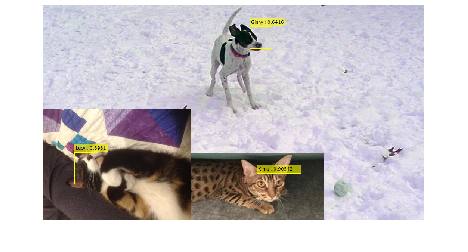

imshow(detectedImage)

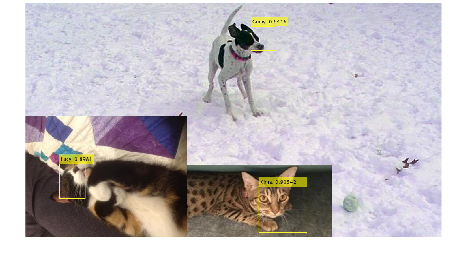

% 1.2. Figure
imshow(imread("Q3_answer1.jpg"))

###     1.3. Threshold detection (5)

     Apply a threshold to the results to only include confident predictions. Extract detections above 85% confidence as the figure in the right pane.

idx = scores > 0.85

idx = 3×1 logical 배열
   1
   1
   0


threshImage = insertObjectAnnotation(testImage, "rectangle",...
    bboxes(idx, :), newlabels(idx, :))

threshImage = 575×1020×3 uint8 배열
threshImage(:,:,1) =

   190   191   193   194   194   193   191   190   192   199   207   211   210   207   205   205   203   199   196   198   203   208   207   206   206   209   208   203   200   202   201   200   199   197   195   195   198   202   205   207   207   209   211   209   203   195   190   187   189   193   197   199   203   207   207   205   203   201   200   204   211   215   210   202   204   204   205   206   208   213   220   224   219   211   204   203   200   196   195   197   198   200   201   202   204   208   210   210   211   212   213   214   213   210   207   205   203   203   202   202   202   203   204   205   209   210   210   211   212   213   213   214   218   216   212   206   201   199   202   206   212   214   219   221   217   209   205   205   204   203   202   203   204   205   206   206   207   212   217   217   213   209   206   206   206   207   207   206   203   202   201   202   202   202   202   202   203  

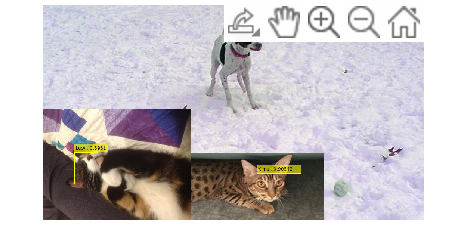

imshow(threshImage)

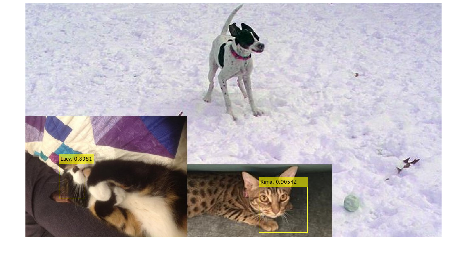

% 1.3. Figure
imshow(imread("Q3_answer2.jpg"))